# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 2022-05-19 01:50:17

## Set up the Import Options and import the data

clear
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["DisplacementmmFDCurve", "ForceNFDCurve"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
% tbl = readtable("220519 - FD.txt", opts);
% tbl1 = readtable("220519 - V.txt", opts);
% tbl2 = readtable("220519 - FD-2.txt", opts);
% tbl3 = readtable("220519 - V-2.txt", opts);
tbl = readtable("220519 - FD-3.txt", opts);
tbl1 = readtable("220519 - V-3.txt", opts);

## Convert to output type

% DF(:,1) = tbl.DisplacementmmFDCurve(1:1000).*1e-3;
% F(:,1) = tbl.ForceNFDCurve(1:1000);
% 
% DV(:,1) = tbl1.DisplacementmmFDCurve(1:1000).*1e-3;
% V(:,1) = tbl1.ForceNFDCurve(1:1000);
DF(:,1) = tbl.DisplacementmmFDCurve.*1e-3;
F(:,1) = tbl.ForceNFDCurve*9.81^2; % LabVIEW에서 생각을 잘못해서 9.81로 곱해야 되는 것을 나누어버림

DV(:,1) = tbl1.DisplacementmmFDCurve.*1e-3;
V(:,1) = tbl1.ForceNFDCurve;

% DF(:,2) = tbl2.DisplacementmmFDCurve;
% F(:,2) = tbl2.ForceNFDCurve;
% 
% DV(:,2) = tbl3.DisplacementmmFDCurve;
% V(:,2) = tbl3.ForceNFDCurve;

## Clear temporary variables

clear opts tbl tbl1 tbl2 tbl3

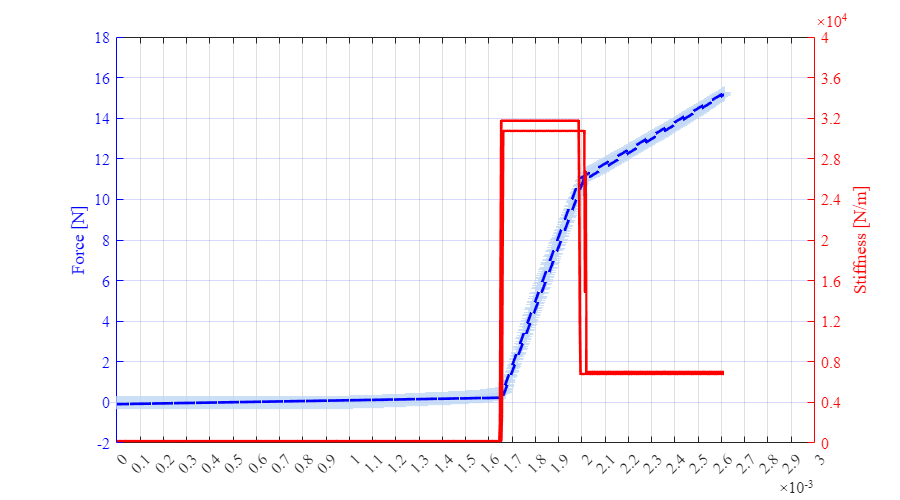

% Create figure
figure1 = figure('NumberTitle','off','Name','Figure','Color',[1 1 1],'Position',[100 100 100+800 100+400]);

% Create axes
axes1 = axes('Parent',figure1);
hold(axes1,'on');

% Activate the left side of the axes
yyaxis(axes1,'left');
% Create multiple lines using matrix input to plot
plot1(1) = plot(DF,F,'+','DisplayName','Force [N]','Color', [0.75 0.75 0.75]);

[TF,S1,S2] = ischange(F,'linear','MaxNumChanges',5);
segline = S1.*(1:2000)' + S2;
plot1(2) = plot(DF,segline);

set(plot1(1),'DisplayName','Force [N]',...
    'MarkerFaceColor',[0.800000011920929 0.800000011920929 0.800000011920929],...
    'MarkerEdgeColor',[0.729411780834198 0.831372559070587 0.95686274766922],...
    'MarkerSize',10,...
    'Marker','+',...
    'LineStyle','none',...
    'Color',[0.75 0.75 0.75]);
set(plot1(2),'LineWidth',2,'LineStyle','--','Color',[0 0 1]);

% Create ylabel
ylabel('Force [N]');
% Uncomment the following line to preserve the Y-limits of the axes
% ylim(axes1,[0 0.2]);

% Set the remaining axes properties
% set(axes1,'YColor',[0 0.447 0.741]);
set(axes1,'YColor',[0 0 1]);
% Activate the right side of the axes
yyaxis(axes1,'right');
% Create plot
K = abs(gradient(segline,DF(2)-DF(1)));
plot(DF,K,'LineWidth',2,'LineStyle','-','Color',[1 0 0]);

% Create ylabel
ylabel('Stiffness [N/m]');
% Uncomment the following line to preserve the Y-limits of the axes
ylim(axes1,[0 40000]);

% Set the remaining axes properties
set(axes1,'YColor',[1 0 0],'YDir','normal','YMinorTick','off',...
    'YTick',[0 4000 8000 12000 16000 20000 24000 28000 32000 36000 40000]);
% Uncomment the following line to preserve the X-limits of the axes
xlim(axes1,[0 0.003]);
box(axes1,'on');
hold(axes1,'off');
% Set the remaining axes properties
set(axes1,'FontName','Times New Roman','FontSize',12,'XGrid','on','XTick',...
    [0 0.0001 0.0002 0.0003 0.0004 0.0005 0.0006 0.0007 0.0008 0.0009 0.001 0.0011 0.0012 0.0013 0.0014 0.0015 0.0016 0.0017 0.0018 0.0019 0.002 0.0021 0.0022 0.0023 0.0024 0.0025 0.0026 0.0027 0.0028 0.0029 0.003],...
    'YGrid','on');

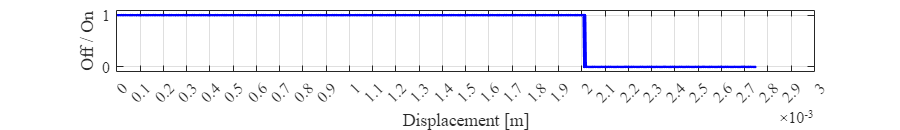



% Create figure
figure2 = figure('NumberTitle','off','Name','Figure','Color',[1 1 1],'Position',[100 100 100+800 100+30]);

% Create axes
axes2 = axes('Parent',figure2);
hold(axes2,'on');

% Create plot
ONOFF = logical(V>0.1);
plot(DV, ONOFF,'LineWidth',2,'Color',[0 0 1]);

% Create ylabel
ylabel('Off / On');

% Create xlabel
xlabel('Displacement [m]');

% Uncomment the following line to preserve the X-limits of the axes
xlim(axes2,[0 0.003]);
% Uncomment the following line to preserve the Y-limits of the axes
ylim(axes2,[-0.1 1.1]);
box(axes2,'on');
hold(axes2,'off');
% Set the remaining axes properties
set(axes2,'FontName','Times New Roman','FontSize',12,'XGrid','on','XTick',...
    [0 0.0001 0.0002 0.0003 0.0004 0.0005 0.0006 0.0007 0.0008 0.0009 0.001 0.0011 0.0012 0.0013 0.0014 0.0015 0.0016 0.0017 0.0018 0.0019 0.002 0.0021 0.0022 0.0023 0.0024 0.0025 0.0026 0.0027 0.0028 0.0029 0.003],...
    'YGrid','on','YTick',[0 1]);